N = 11;
L = 4;
M = 4;

H = pow(2:42,2:N+2);
t_vec = pow(2:42,1);

Hd = (H(2:41,:)- H(1:40,:))/5;

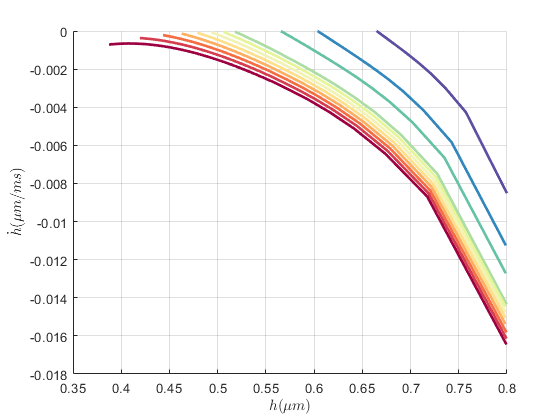

C = linspecer(N);
figure; hold on;
for i=1:N
    plot(H(1:40,i),Hd(1:40,i),'color',C(i,:),"LineWidth",2)
end
ylabel('$\dot{h} (\mu m/ms)$','Interpreter','Latex')
xlabel('$h (\mu m)$','Interpreter','Latex')
grid on;

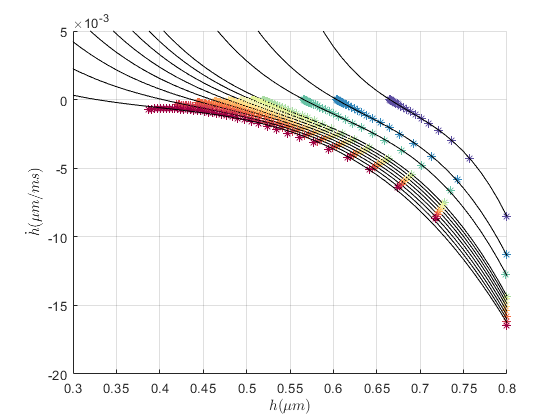

C = linspecer(N);
p = zeros(N,L);
figure; hold on;
hvec = 0:0.01:0.8;
for i=1:N
    plot(H(1:40,i),Hd(1:40,i),'color',C(i,:),'LineStyle','none',"Marker","*")
    [p(i,:),S] = polyfit(H(1:40,i),Hd(1:40,i),L-1);
    y = polyval(p(i,:),hvec);
    plot(hvec,y,'k');
end
ylabel('$\dot{h} (\mu m/ms)$','Interpreter','Latex')
xlabel('$h (\mu m)$','Interpreter','Latex')
ylim([-20e-3 5e-3])
xlim([0.3 0.8])
grid on;

pow_vec = pow(1,2:N+1);


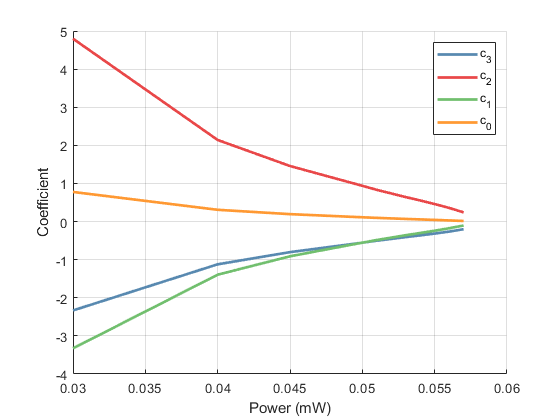

C = linspecer(L);
figure; hold on;
for i=1:L
    plot(pow_vec,p(:,i),'color',C(i,:),"LineWidth",2)
end
ylabel('Coefficient')
xlabel('Power (mW)')
grid on;
legend('c_3','c_2','c_1','c_0')

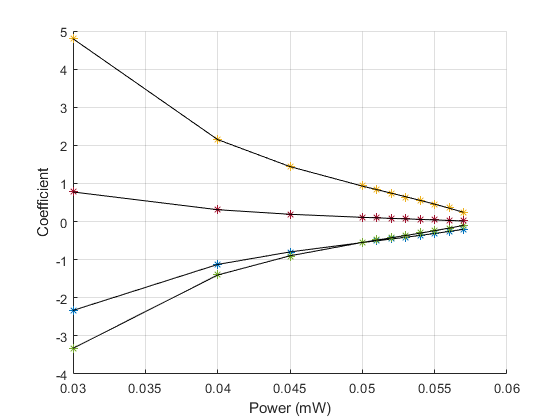

pc = zeros(L,M);
figure; hold on;
for i=1:L
    plot(pow_vec,p(:,i),'LineStyle','none',"Marker","*")
    [pc(i,:),S] = polyfit(pow_vec,p(1:N,i),M-1);
    y = polyval(pc(i,:),pow_vec);
    plot(pow_vec,y,'k');
end
ylabel('Coefficient')
xlabel('Power (mW)')
grid on;

% ht = 0.8;
% pt_vec = 0:0.001:0.08;
% hdt = [pt_vec'.^3 pt_vec'.^2 pt_vec'.^1 pt_vec'.^0 ]*pc'*[ht^3; ht^2; ht; 1];
% figure;
% plot(pt_vec,hdt);

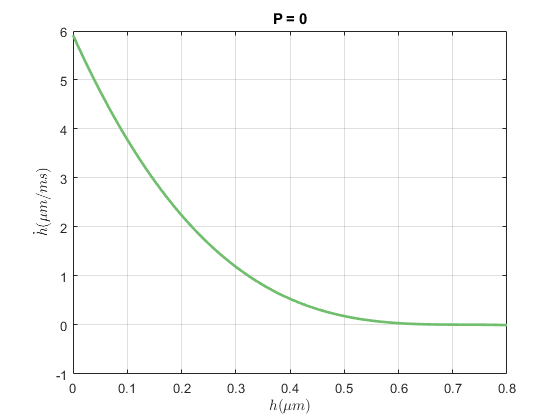

pt = 0.00;
ht_vec = 0.0:0.01:0.8;
hdt = [pt^3 pt^2 pt^1 pt^0 ]*pc'*[ht_vec.^3; ht_vec.^2; ht_vec.^1;ht_vec.^0];
figure;
plot(ht_vec,hdt,'LineWidth',2,"Color",C(3,:));
ylabel('$\dot{h} (\mu m/ms)$','Interpreter','Latex')
xlabel('$h (\mu m)$','Interpreter','Latex')
title('P = 0')
grid on;

hres = restore(:,2);
tres = restore(:,1);
hdres = hres(2:48)-hres(1:47);

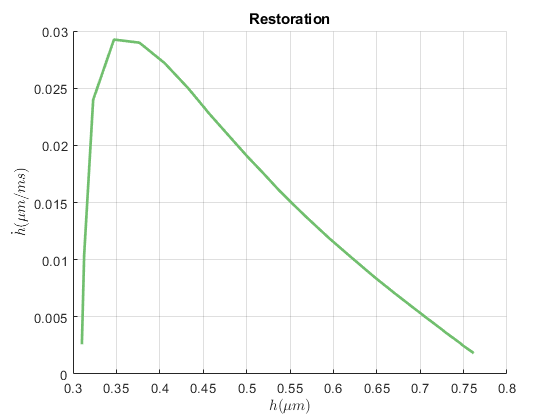

figure; hold on;
plot(hres(1:47),hdres,'LineWidth',2,"Color",C(3,:));
ylabel('$\dot{h} (\mu m/ms)$','Interpreter','Latex')
xlabel('$h (\mu m)$','Interpreter','Latex')
title('Restoration')
grid on;